# 5CCE2MCT - Embedded Control & DAQ

*© Copyright of King's College London, Dept of Engineering 2022*

**Learning Objectives**

- Describe the electromechanical components available for the group project and practice how to interface with them via Simulink and / or Arduino IDE

- Troubleshoot common hardware connectivity problems

- Characterise the behaviour of a component from acquired data. 

- Control a component in open-loop

- Explain what is meant by rate control and critique time resolution trade-offs for embedded system design

## Arduino Programming from Simulink 

This tutorial will introduce you to how to program an Arduino board with Simulink, which is a powerful design tool for control system design. 

### Setup

Before you start, you will have to:

- install [MATLAB Desktop R2021b or above](https://www.mathworks.com/academia/tah-portal/kings-college-london-30860095.html), with Simulink

- install the Simulink support package for Arduino boards. 

**Installing Additional Toolboxes and Support Packages**

From the MATLAB Toolstrip, under `HOME > Environment > Add-Ons` select  

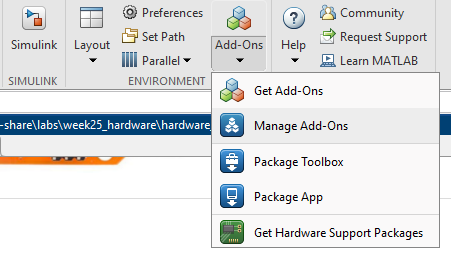

Make sure the Simulink Support Package Arduino Hardware is installed.You can search for "simulink arduino" using the search bar to find the support package.  

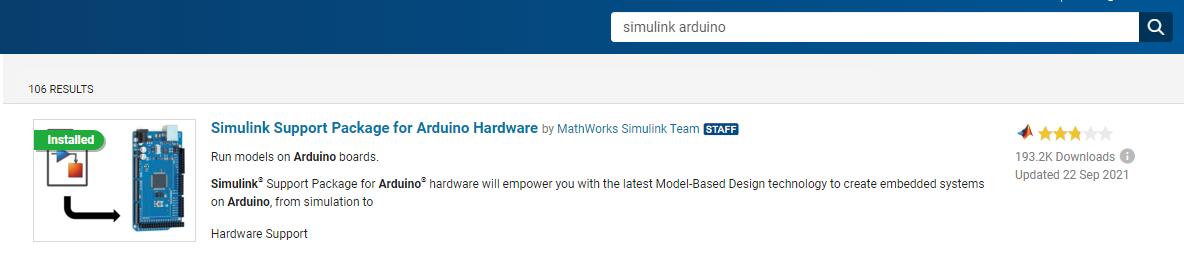

Follow the guided setup for installation of the support package and for first time board setup.

### Board Setup & Drivers

You can repeat a hardware setup for an Arduino board from 

Click the cog on the right-hand side of the package to open the guided setup dialogs. 

### Checking Driver Installation

Check that the drivers for the board have been installed correctly. 

Open Device manager in Windows and inspect the available drivers attached to the COM ports. 

The driver should be labelled with the name of the board, e.g. Arduino NANO 33 IoT 

Double-click reset button to put board in bootloader mode

The reset button is labelled `RST` on the board and is highlighted in the figure below. 

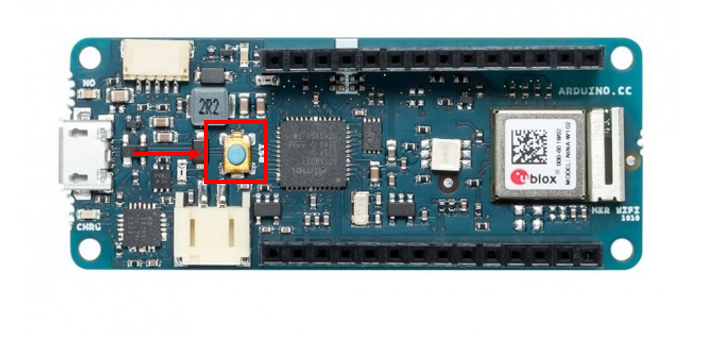

**--> Make a note of the COM port number for both the board and bootloader - we will need these later. <--**

If the board does not appear with the correct name, you will have to install the board drivers manually. 

This can be done by right-clicking on the device and clicking the Update driver option in the dialog. 

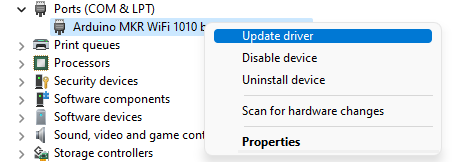

Choose the manual option for installation.

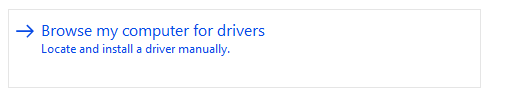

Install by searching for the driver from the MATLAB Support Package installation folder (make sure you search in the `aIDE\portable folder)`, an example below (can vary depending on installation):

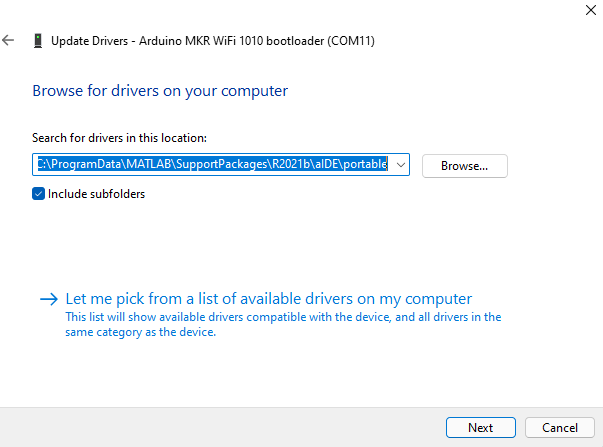

Repeat the driver installation in both normal and bootloader modes. 

### Hello World - Standalone vs External Mode

Implement the following dimmer-switched LED on a breadboard

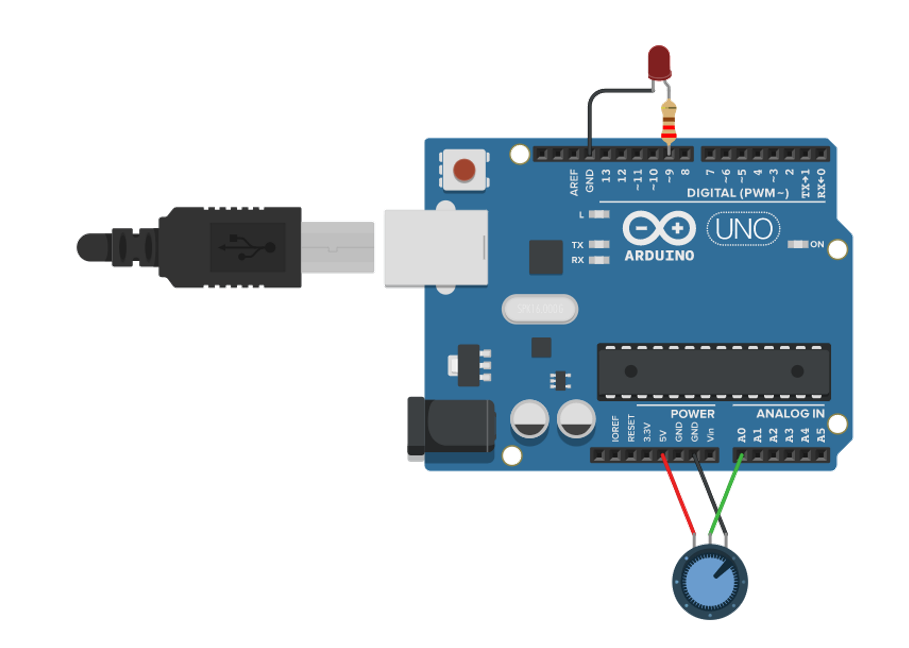

We will examine how to deploy code from SImulink to make this system work. 

Open a blank model in Simulink

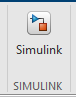

simulink

### Create model using driver blocks

Import the `Analog Input` and `PWM` blocks from the Simulink library by clicking in the canvas and typing the block name

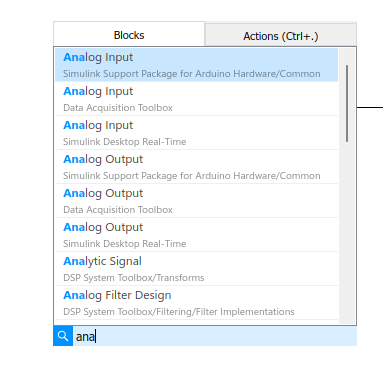

Make sure to select blocks from the Simulink Support Package for Arduino Hardware.

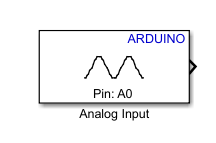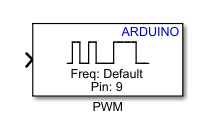

Connect them as below

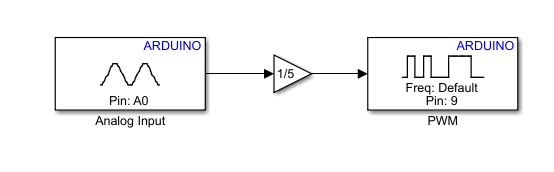

### Hardware setup configuration

Under Simulink Toolstrip, select `APPS` dropdown. 

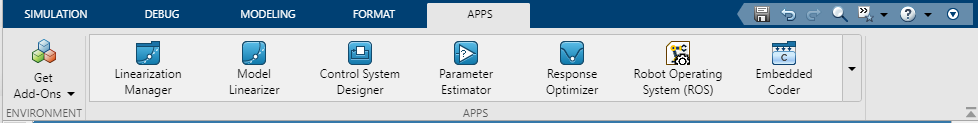

Scroll to `Run on Hardware Board`

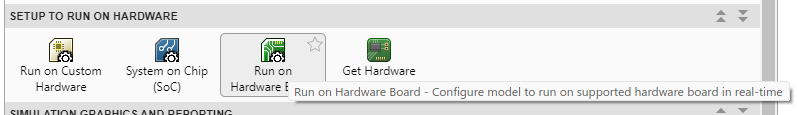

You can choose Arduino Uno for the board you want to deploy to:

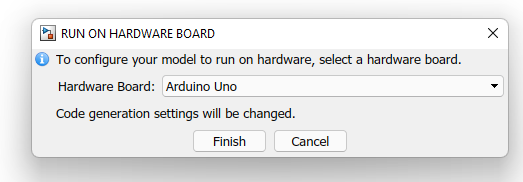

Note the new toolstrip menu named HARDWARE

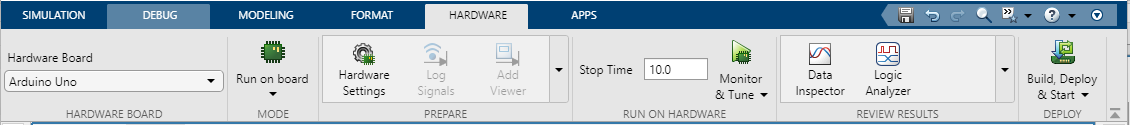

and that the solver has changed to fixed step in the bottom-right corner.

Access hardware deployment options in the Model Configuration menu (`Ctrl + E`), under Hardware Implementation

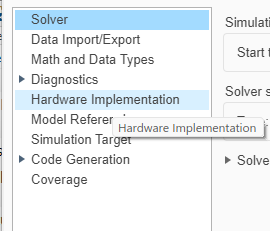

Configure the COM port manually if you are having trouble with automatic COM port search. Remember you can find the COM port of your Arduino board from the computer's Device manager. 

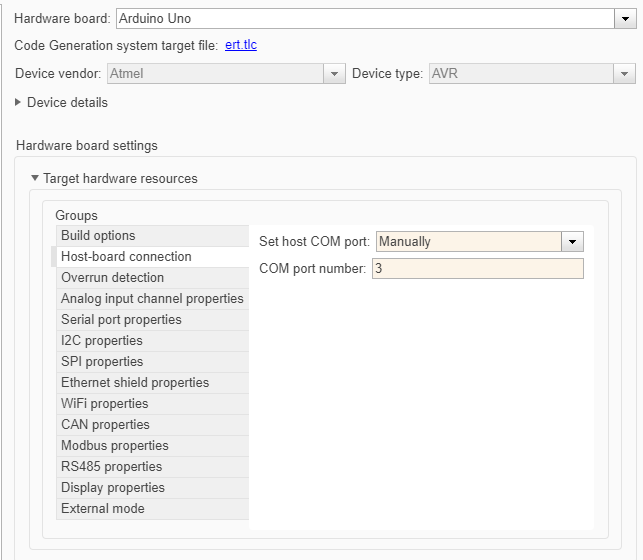

### Hardware Target Deployment - Standalone vs External mode

Return to Simulink model. 

**Standalone mode**

In standalone mode, you upload C code that is generated from your Simulink model to the Arduino board. This mode is useful for when you finally deploy your project. 

Run models in standalone using Build, Load & Run

**External mode**

In external mode, you maintain a live connection between Simulink and the Arduino over XCP serial communication. This mode is useful for desktop prototyping, as you can visualise signals read by the Arduino from Simulink. 

**Exercise: **Add a scope block to the Simulink Canvas

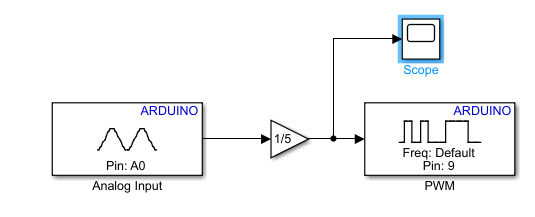

and run model in External mode using the Monitor & Tune option. 

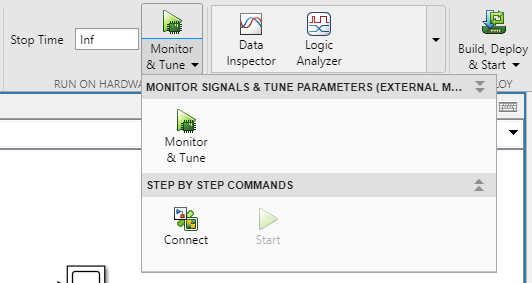

When you open the scope, you will notice that you are reading the analog measurements from the potentiometer sensors. 

### Motor control

The Arduino Nano Motor Carrier contains a voltage divider circuit and an H-bridge that will allow you to run the DC motor both forward and in reverse. In the following tutorial, you will learn the basics of motor control. 

#### Connecting hardware

Plug the Arduino board into the Arduino Motor Carrier. 

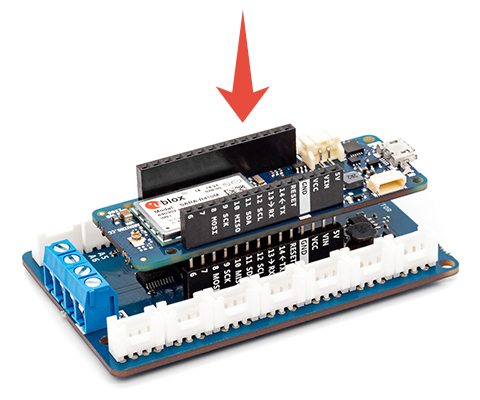

**Motor Power: **Connect the M1 and M2 terminals of the DC motor to the M3+ and M3- screw terminal on the Arduino MKR Motor Carrier. 

**Rotary Encoder: **Connect the Vcc and Ground terminals of the DC motor encoder to the 3.3V and GND screw terminal on the Arduino MKR Motor Carrier. Connect the C1 and C2 terminals of the DC motor encoder to the HB1 and HA1 screw terminals on the Arduino Motor Carrier. 

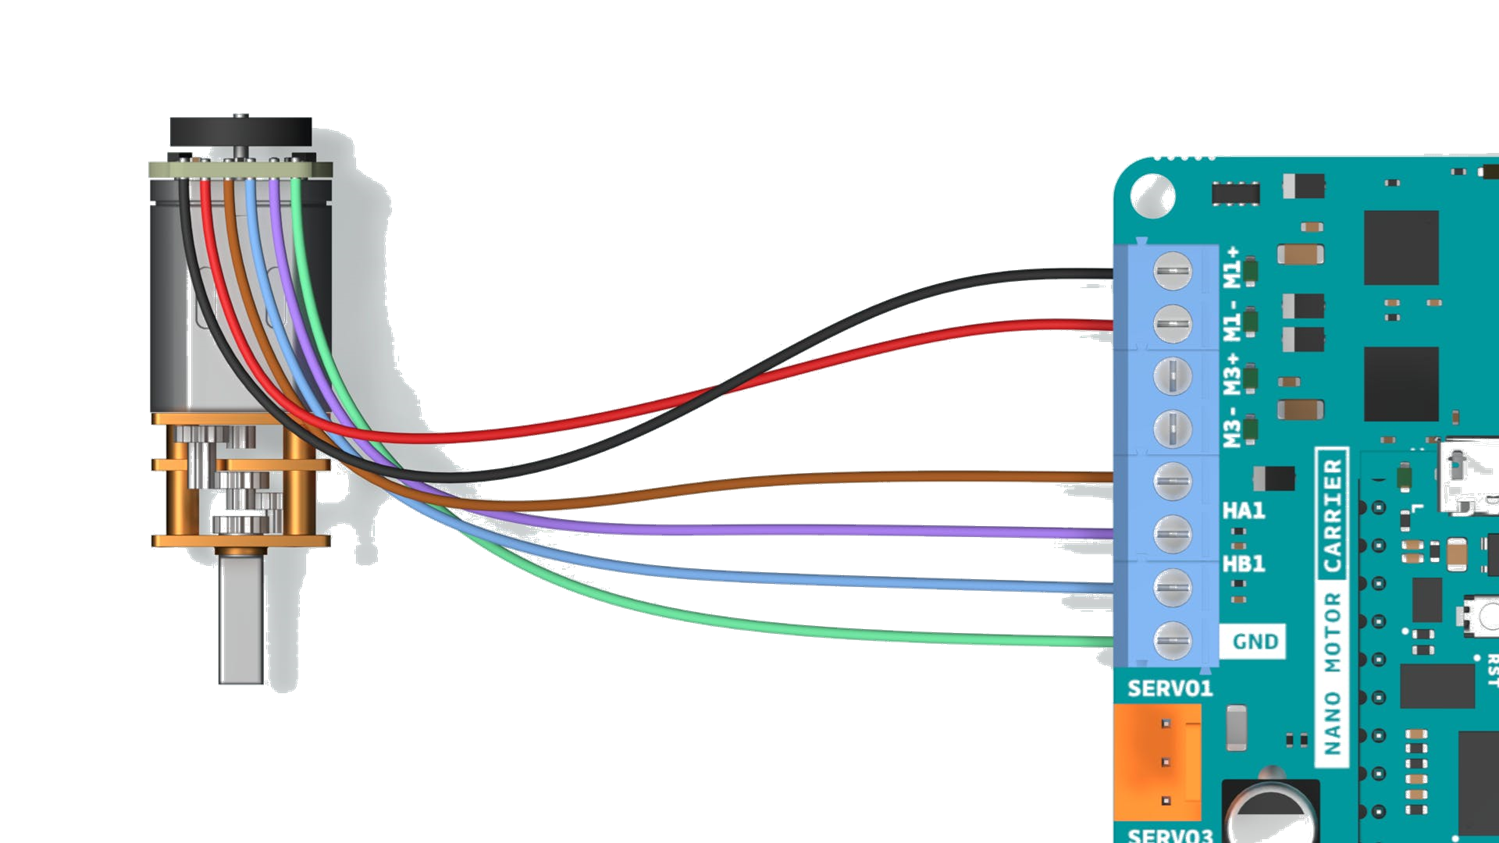    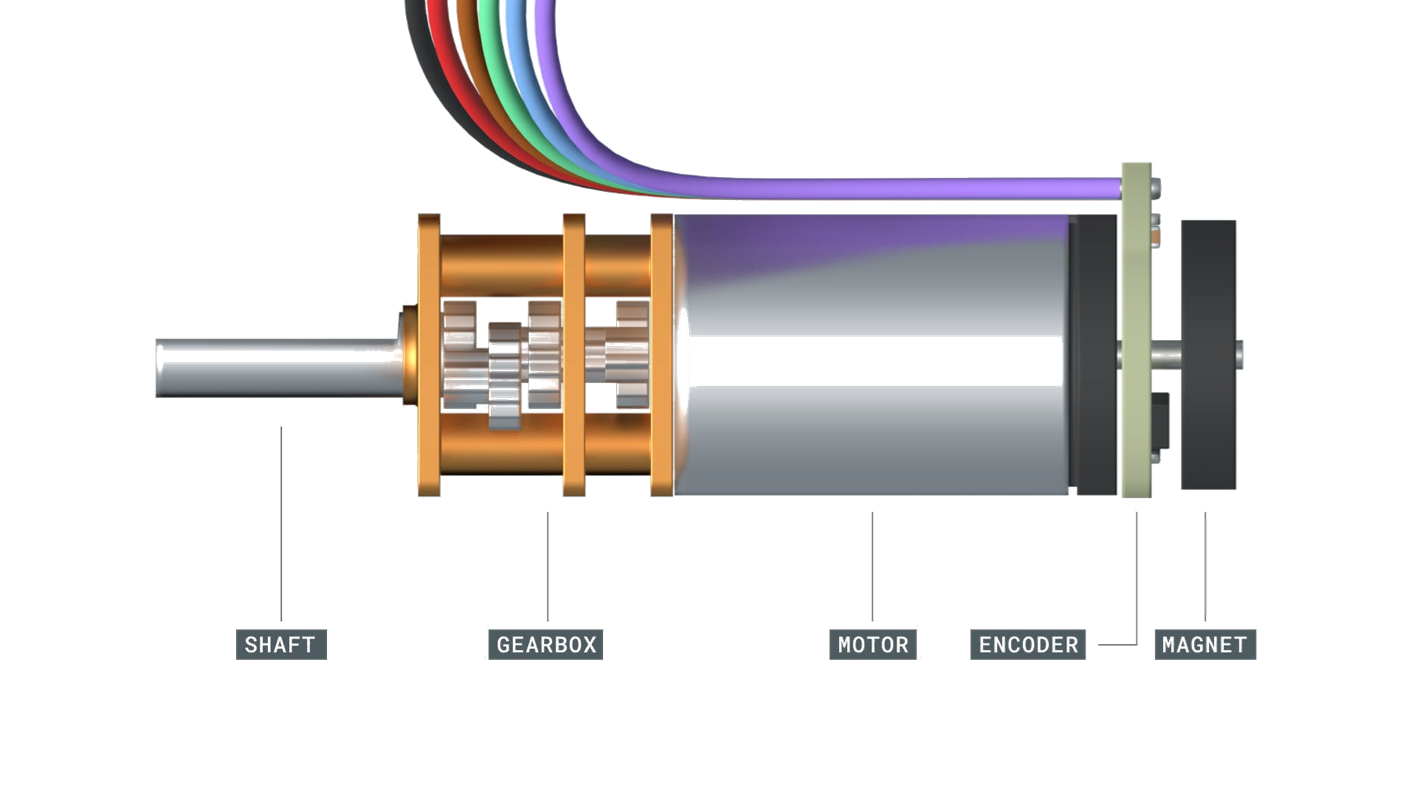

#### Running the motors

Run the model below to run the motors and measure their rotational velocity.

  open_system('motor_control.slx')

*N.B. the rotary encoder measures position as a count of pulses detected from a Hall sensor. The count reading is convert to position and then filters into its derivative using the Discrete Derivative filter block. *

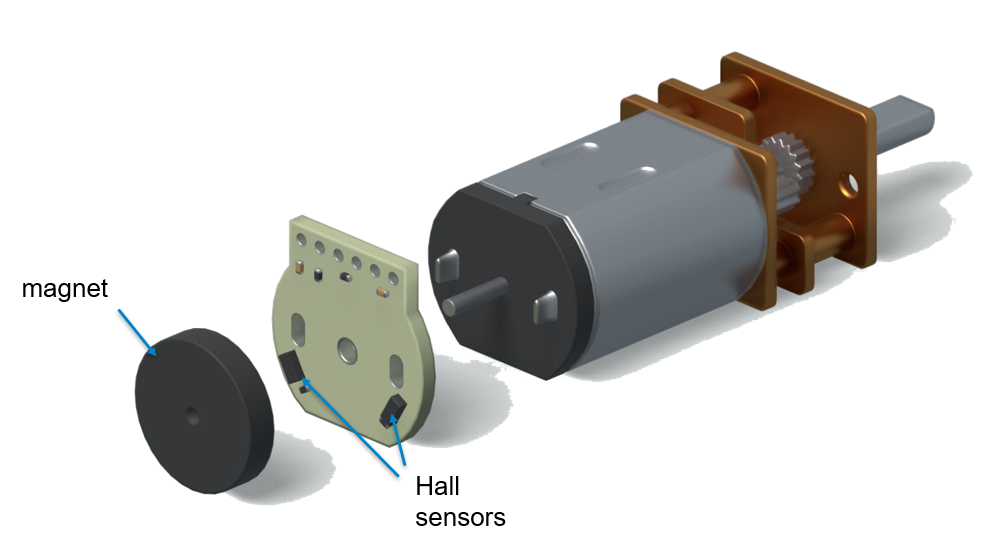

#### Feedback control on a DC motor

**Exercise:** Tune the PID controller to in the model below:

  open_system('motor_feedback_control.slx')

### Servomotor

**Exercise: **Control the angular position of a servomotor. 

  open_system('servomotor_control.slx')

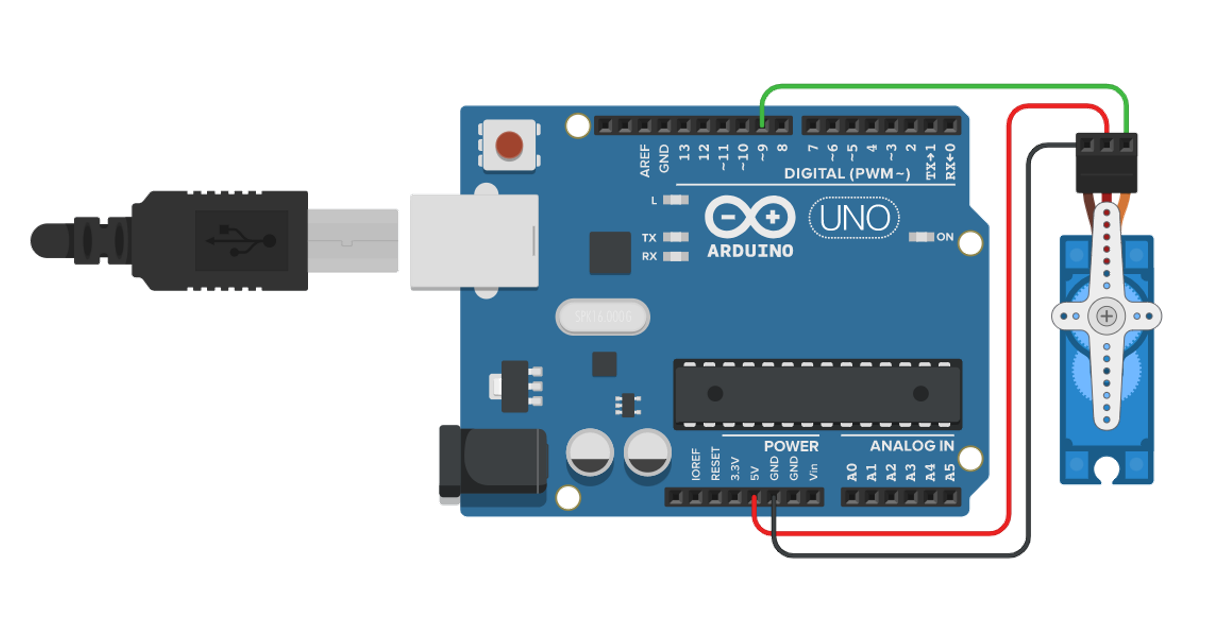 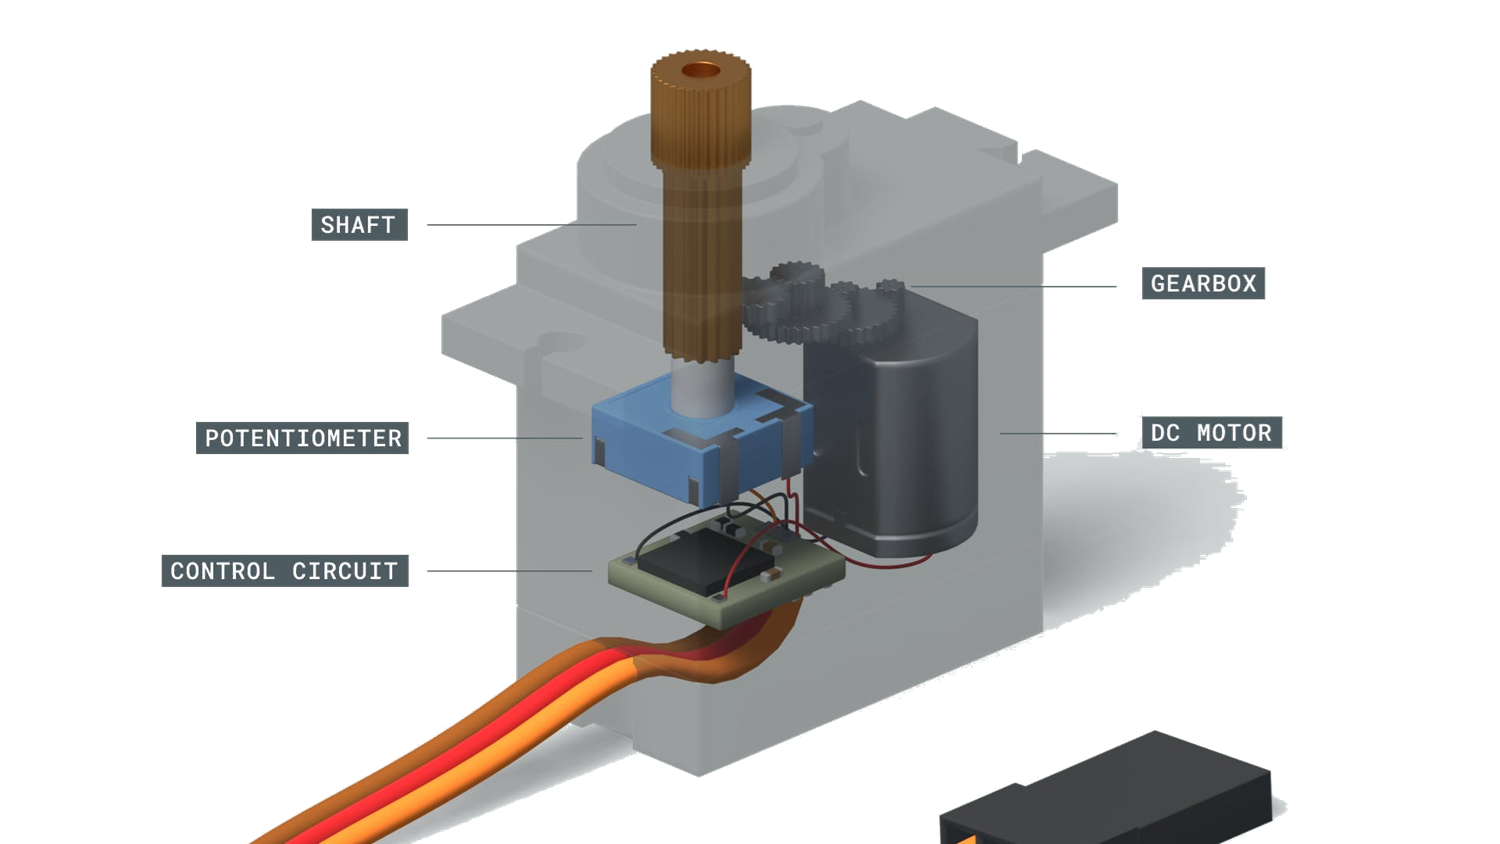

### Communication

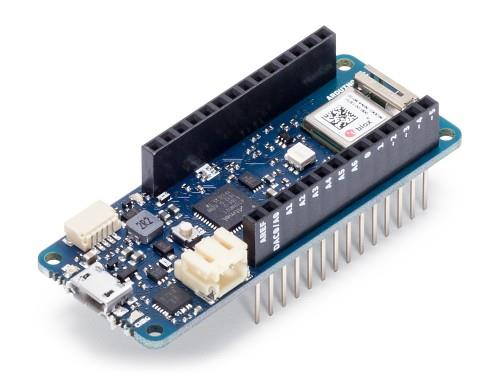         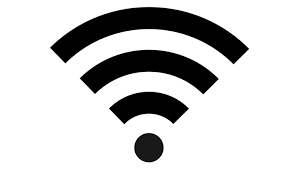   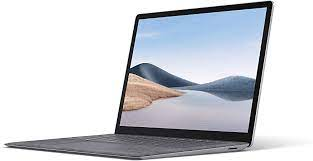

#### Wi-Fi UDP

  

open_system('wifi_send.slx')        % send UDP messages from Arduino MKR board
open_system('wifi_receive.slx')     % receive on PC